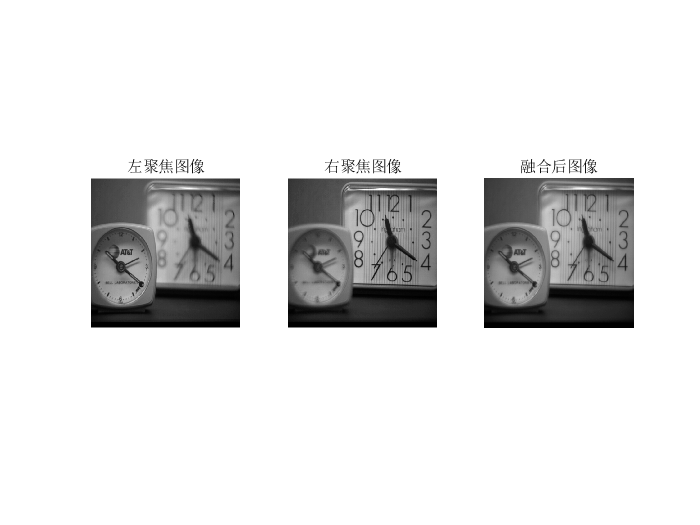

close all; clear; clc;
I1 = imread('左聚焦图像.bmp');
I2 = imread('右聚焦图像.bmp');
if size(I1,3) == 3
    I1 = rgb2gray(I1);
end
if size(I2,3) == 3
    I2 = rgb2gray(I2);
end
I1 = double(I1);
I2 = double(I2);
[res,pcaWeightCoef] = PcaFusion(I1,I2);
figure;
subplot(131),imshow(I1,[]),title('左聚焦图像');
subplot(132),imshow(I2,[]),title('右聚焦图像');
subplot(133),imshow(res,[]),title('融合后图像');